# Exercise: Multidomain electro-mechanical system

The cage of an elevator is hoisted by a long cable wound over a drum driven through a gear-set by an electric motor. The motor is relay-operated (i.e., either on or off) and the resulting abrupt transients cause the cage to oscillate on the hoisting cable. Because the cable has low internal friction, the oscillations persist for many cycles.

Please not that the motor armature resistance and inductance may be neglected and also drum and gear inertia may be neglected.

To solve this problem it has been proposed to introduce an electrical R-C filter between the relay and the motor terminals. The designer claims that this will smooth the transient, thereby reducing the oscillation amplitude to acceptable levels. Your task is to evaluate this proposal. does electrical filtering help?

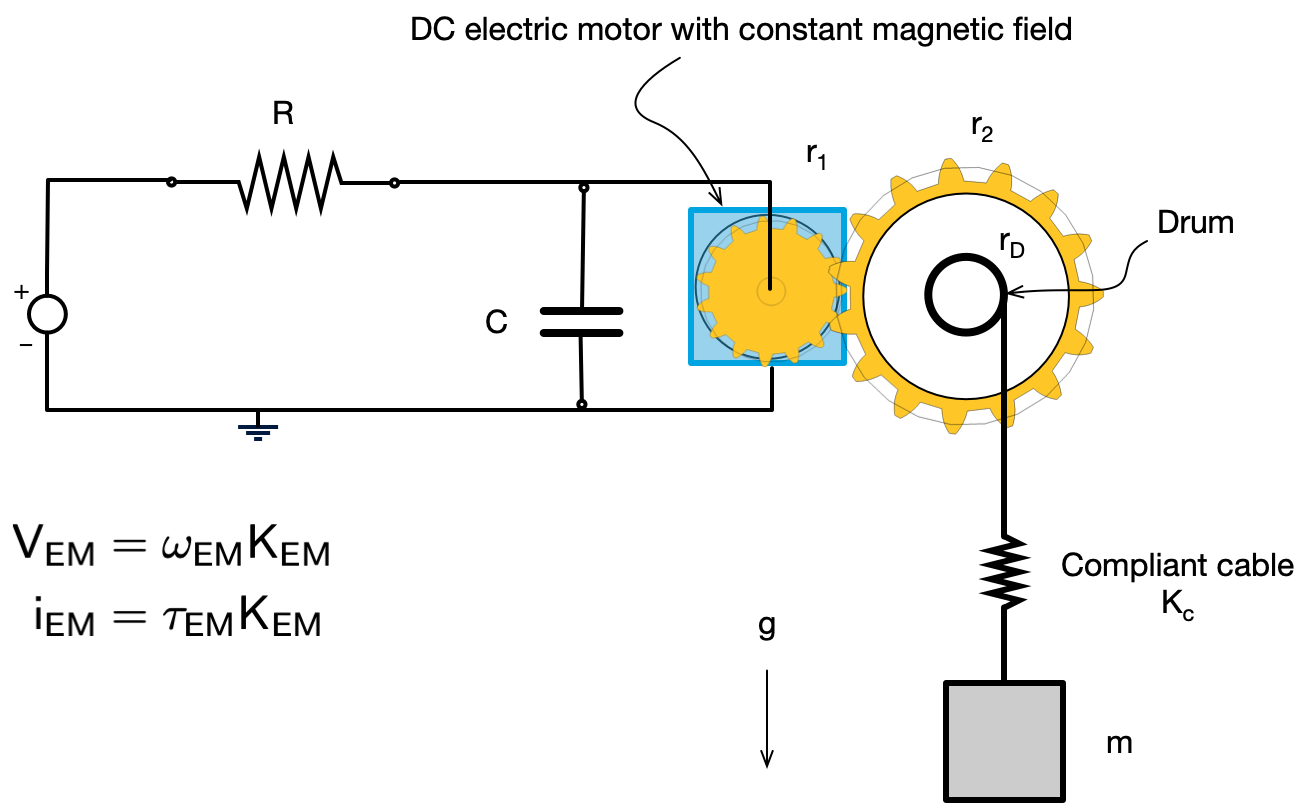

- The mass is an A-type element (1 edge)

- The cable is a T-type element (spring) (1 edge)

- The drum  set is transformer  (2 edges )

- The  gear set is transformer  (2 edges )

- The eletric motor is a coupler/gyrator (2 edges )

- The capacitance is a A-type element (1 edge)

- The resistor is a D-type element (1 edge)

- The VOltage sourse is an A-type source (1 edge)

**In total we have 11 edges thus 11 constitutive equations**

## Linear graph and normal tree

System Graph with the normal tree is shown in the picture

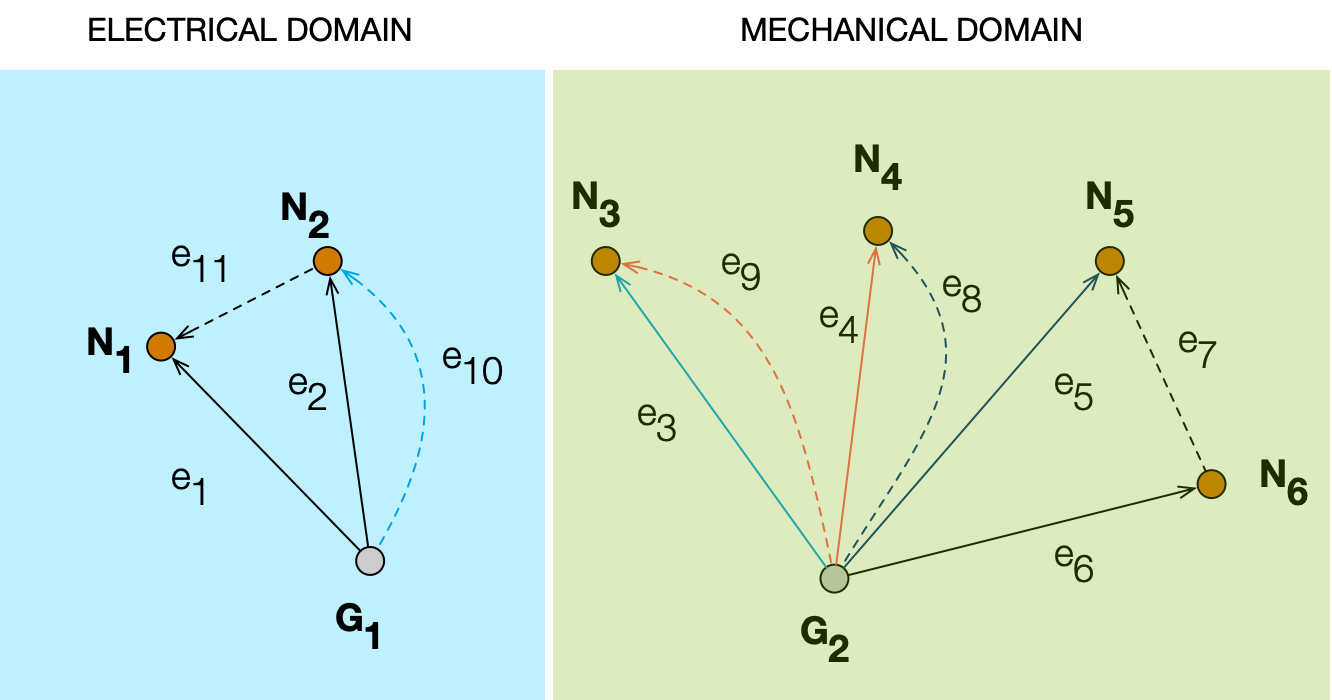

## Definitions

Definition of across and through variables

clc
clear 
close all
%
% library folder to use the utility functions
addpath('MBlibs')


Definition of problem variables

syms t

N = 11; % Number of edges 

% alpha_vars = sym("alpha_%d",[N,0]);
% tau_vars = sym("tau_%d",[N,0]);
alpha_vars = sym.empty(1,0);
tau_vars = sym.empty(1,0);
% number of functions
for k = 1:N
    eval(sprintf('syms tau%d(t)', k));
    eval(sprintf('syms alpha%d(t)', k));
    % Optionally initialize a value: eval(sprintf('alpha%d(t) = 0;', k));
    % Build a row vector of the symbolic functions evaluated at t
     alpha_vars(k) = str2sym(sprintf('alpha%d(t)', k));
    tau_vars(k) = str2sym(sprintf('tau%d(t)', k));
end

tau_vars = tau_vars.';
alpha_vars = alpha_vars.';


## Constitutive equations

We define the constitutive equations for each element (i.e. edge)

**NOTE**: in the constitutive equation of the mass we added the controbution of the gravity as external force acting on the mass without adding the corresponding element in the tree. 

% we add an extra variable which is the spring displacement and one
% additional constitutive equations

syms K_s m V0 r1 r2 r C R K_emf gear_ratio g

% gear_ratio = r1/r2; 

eqns_const = [ % Voltage source
               alpha1(t) == V0
               % capacitor
               diff(alpha2(t),t) == 1/C*tau2(t)
               % resistor
               alpha11(t) == R*tau11(t)
               % electric motor
               alpha3(t) == 1/K_emf*alpha10(t)
               tau3(t)   == -K_emf*tau10(t)
               % gear train
               alpha4(t) == -gear_ratio*alpha9(t)
               tau4(t)   ==  1/gear_ratio*tau9(t)
               % drum
               alpha5(t) ==  r*alpha8(t)
               tau5(t)   == -1/r*tau8(t)
               % spring: defined as differential being alpha8 a velocity
               diff(tau7(t),t) == K_s*alpha8(t)
               % mass
               % NOTE: we also added the gravity as external force
               diff(alpha6(t),t) == 1/m*tau6(t)-g
              ]

$$eqns\_const = \left(\begin{array}{c} \alpha_{1}\left(t\right)=V_{0}\\ \frac{\partial }{\partial t}\alpha_{2}\left(t\right)=\frac{\tau_{2}\left(t\right)}{C}\\ \alpha_{11}\left(t\right)=R\,\tau_{11}\left(t\right)\\ \alpha_{3}\left(t\right)=\frac{\alpha_{10}\left(t\right)}{K_{\mathrm{emf}}}\\ \tau_{3}\left(t\right)=-K_{\mathrm{emf}}\,\tau_{10}\left(t\right)\\ \alpha_{4}\left(t\right)=-{\mathrm{gear}}_{\mathrm{ratio}}\,\alpha_{9}\left(t\right)\\ \tau_{4}\left(t\right)=\frac{\tau_{9}\left(t\right)}{{\mathrm{gear}}_{\mathrm{ratio}}}\\ \alpha_{5}\left(t\right)=r\,\alpha_{8}\left(t\right)\\ \tau_{5}\left(t\right)=-\frac{\tau_{8}\left(t\right)}{r}\\ \frac{\partial }{\partial t}\tau_{7}\left(t\right)=K_{s}\,\alpha_{8}\left(t\right)\\ \frac{\partial }{\partial t}\alpha_{6}\left(t\right)=\frac{\tau_{6}\left(t\right)}{m}-g \end{array}\right)$$

## Loop and node equations

### Incidence matrix

The incidence matrix has tow singular row in this cases. We write directly the matrix without singular rows.

%      e1 e2 e3 e4 e5 e6 e7 e8 e9 e10 e11   
IM = [ 1   0  0  0  0  0  0  0  0   0  1 ;    % N1
       0   1  0  0  0  0  0  0  0   1  -1 ;    % N2
       0   0  1  0  0  0  0  0  1   0   0 ;    % N3
       0   0  0  1  0  0  0  1  0   0   0 ;    % N4
       0   0  0  0  1  0  1  0  0   0   0 ;    % N5
       0   0  0  0  0  1 -1  0  0   0   0 ;    % N6
      -1  -1  0  0  0  0  0  0  0   0   0 ;    % G1
       0   0 -1 -1 -1 -1  0 -1 -1  -1  0 ;    % G2
]

IM =      1     0     0     0     0     0     0     0     0     0     1
     0     1     0     0     0     0     0     0     0     1    -1
     0     0     1     0     0     0     0     0     1     0     0
     0     0     0     1     0     0     0     1     0     0     0
     0     0     0     0     1     0     1     0     0     0     0
     0     0     0     0     0     1    -1     0     0     0     0
    -1    -1     0     0     0     0     0     0     0     0     0
     0     0    -1    -1    -1    -1     0    -1    -1    -1     0


[nn,ne] = size(IM);

% Check system consistency
if ~(length(alpha_vars) == ne )
  error 'Inconsistent dimensions'
end
% row reduced Echelon Form.
rref(IM)

ans =      1     0     0     0     0     0     0     0     0     0     1
     0     1     0     0     0     0     0     0     0     0    -1
     0     0     1     0     0     0     0     0     1     0     0
     0     0     0     1     0     0     0     1     0     0     0
     0     0     0     0     1     0     1     0     0     0     0
     0     0     0     0     0     1    -1     0     0     0     0
     0     0     0     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     0     0     0     0


Two rows are lineraly dependent since they correspond to the ground

rank(IM)

ans = 7

%IM*tau_vars
% Number of elements, number of branches and number of chords
% Reduced Incidence Matrix
nb = nn-2;  % n_nodes-1
ne ;        % number of edges
nc = ne-nb; % number of chords
%reduced IM: ground node is deleted

A = sym(IM(1:nb,1:ne))

$$A = \left(\begin{array}{ccccccccccc} 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & -1\\ 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 1 & -1 & 0 & 0 & 0 & 0 \end{array}\right)$$

% compute Af matrix: Af = [Ib | Ac]
Af = rref(A)

$$Af = \left(\begin{array}{ccccccccccc} 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & -1\\ 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 1 & -1 & 0 & 0 & 0 & 0 \end{array}\right)$$

Ac = Af(:,nb+1:end)  % Ac = Af(1:nb,nb+1:ne);

$$Ac = \left(\begin{array}{ccccc} 0 & 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 1 & -1\\ 0 & 0 & 1 & 0 & 0\\ 0 & 1 & 0 & 0 & 0\\ 1 & 0 & 0 & 0 & 0\\ -1 & 0 & 0 & 0 & 0 \end{array}\right)$$

### Node equations (i.e. Newton Equations at nodes)

Node equations are derived from the rows of rowEchelon form of the reduced incidence matrix: they are the **fundamental cutsets  **$\mathbf{A}_f = [\mathbf{I}_b | \mathbf{A}_C] $.

node_eqns = tau_vars(1:nb)==-Ac*tau_vars(nb+1:ne)

$$node\_eqns = \left(\begin{array}{c} \tau_{1}\left(t\right)=-\tau_{11}\left(t\right)\\ \tau_{2}\left(t\right)=\tau_{11}\left(t\right)-\tau_{10}\left(t\right)\\ \tau_{3}\left(t\right)=-\tau_{9}\left(t\right)\\ \tau_{4}\left(t\right)=-\tau_{8}\left(t\right)\\ \tau_{5}\left(t\right)=-\tau_{7}\left(t\right)\\ \tau_{6}\left(t\right)=\tau_{7}\left(t\right) \end{array}\right)$$

### Circuits equations/Loop equations

We find the **fundamental circuits** from the Af matrix. The Bf matrix which is the circuit loop matrix is derived as null space of matrix Af. $\mathbf{B}_f = [ \mathbf{B}_b | \mathbf{I}_c] $

Bf = null(Af).'

$$Bf = \left(\begin{array}{ccccccccccc} 0 & 0 & 0 & 0 & -1 & 1 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & -1 & 0 & 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & -1 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0\\ 0 & -1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0\\ -1 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 \end{array}\right)$$

Af*Bf'

$$ans = \left(\begin{array}{ccccc} 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

We compute the Bb matrix explointing the principle of 

Bb = -Ac'

$$Bb = \left(\begin{array}{cccccc} 0 & 0 & 0 & 0 & -1 & 1\\ 0 & 0 & 0 & -1 & 0 & 0\\ 0 & 0 & -1 & 0 & 0 & 0\\ 0 & -1 & 0 & 0 & 0 & 0\\ -1 & 1 & 0 & 0 & 0 & 0 \end{array}\right)$$

Ic = Bf(:,nc+1:ne)

$$Ic = \left(\begin{array}{cccccc} 1 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 1 \end{array}\right)$$

#### Loop equations

% Bb = Bf(:,1:nb)
% Ic = Bf(:,nc:ne)

Branch across variables as function of across chords variables

loop_eqns = alpha_vars(nb+1:ne)==-Bb*alpha_vars(1:nb) 

$$loop\_eqns = \left(\begin{array}{c} \alpha_{7}\left(t\right)=\alpha_{5}\left(t\right)-\alpha_{6}\left(t\right)\\ \alpha_{8}\left(t\right)=\alpha_{4}\left(t\right)\\ \alpha_{9}\left(t\right)=\alpha_{3}\left(t\right)\\ \alpha_{10}\left(t\right)=\alpha_{2}\left(t\right)\\ \alpha_{11}\left(t\right)=\alpha_{1}\left(t\right)-\alpha_{2}\left(t\right) \end{array}\right)$$

## DAE system of equations 

### Dependent and independent coordinates

The **dependent variables** are the set of **chord across coordinates** and of the **throught branch coordinates**:

% dependent set of equations from loop and node equations
qvars_d = [lhs(node_eqns); lhs(loop_eqns)]

$$qvars\_d = \left(\begin{array}{c} \tau_{1}\left(t\right)\\ \tau_{2}\left(t\right)\\ \tau_{3}\left(t\right)\\ \tau_{4}\left(t\right)\\ \tau_{5}\left(t\right)\\ \tau_{6}\left(t\right)\\ \alpha_{7}\left(t\right)\\ \alpha_{8}\left(t\right)\\ \alpha_{9}\left(t\right)\\ \alpha_{10}\left(t\right)\\ \alpha_{11}\left(t\right) \end{array}\right)$$


% independent set of DAE variables
allvars = [alpha_vars;tau_vars;];
dae_vars = setdiff(allvars,qvars_d) % dae_vars

$$dae\_vars = \left(\begin{array}{c} \alpha_{1}\left(t\right)\\ \alpha_{2}\left(t\right)\\ \alpha_{3}\left(t\right)\\ \alpha_{4}\left(t\right)\\ \alpha_{5}\left(t\right)\\ \alpha_{6}\left(t\right)\\ \tau_{7}\left(t\right)\\ \tau_{8}\left(t\right)\\ \tau_{9}\left(t\right)\\ \tau_{10}\left(t\right)\\ \tau_{11}\left(t\right) \end{array}\right)$$

### Assembling and solving equations

% Substitute loop equantions into constitutive equations
%subs( eqns_const, sym2cell(lhs(eqns_loop)),sym2cell(rhs(eqns_loop)))
tmp = subs( eqns_const, lhs(loop_eqns),rhs(loop_eqns));
% substitute node equations
dae_eqns = subs( tmp, lhs(node_eqns), rhs(node_eqns))

$$dae\_eqns = \left(\begin{array}{c} \alpha_{1}\left(t\right)=V_{0}\\ \frac{\partial }{\partial t}\alpha_{2}\left(t\right)=-\frac{\tau_{10}\left(t\right)-\tau_{11}\left(t\right)}{C}\\ \alpha_{1}\left(t\right)-\alpha_{2}\left(t\right)=R\,\tau_{11}\left(t\right)\\ \alpha_{3}\left(t\right)=\frac{\alpha_{2}\left(t\right)}{K_{\mathrm{emf}}}\\ -\tau_{9}\left(t\right)=-K_{\mathrm{emf}}\,\tau_{10}\left(t\right)\\ \alpha_{4}\left(t\right)=-{\mathrm{gear}}_{\mathrm{ratio}}\,\alpha_{3}\left(t\right)\\ -\tau_{8}\left(t\right)=\frac{\tau_{9}\left(t\right)}{{\mathrm{gear}}_{\mathrm{ratio}}}\\ \alpha_{5}\left(t\right)=r\,\alpha_{4}\left(t\right)\\ -\tau_{7}\left(t\right)=-\frac{\tau_{8}\left(t\right)}{r}\\ \frac{\partial }{\partial t}\tau_{7}\left(t\right)=K_{s}\,\alpha_{4}\left(t\right)\\ \frac{\partial }{\partial t}\alpha_{6}\left(t\right)=\frac{\tau_{7}\left(t\right)}{m}-g \end{array}\right)$$

Check dimensions

if ~(length(qvars_d)==N)
  fprintf('dep. vars %d <> n. elements %d',length(qvars_d),N)
  error 'Inconsistent number of dependent variables'
end
if ~(length(eqns_const)==N)
  fprintf('n. constitutive eqns. %d <> n. elements %d',length(eqns_const),N);
  error 'Constitutive equations must be equal to number of dependent variables'
end
if ~(length(dae_eqns)==length(dae_vars))
  fprintf('n.dae eqns %d <> n. eqns vars %d',length(dae_eqns),length(dae_vars))
  error 'Inconsistent set of equations'
end

### Equations manipulation: index reduction

[E_mat, G_vec] = massMatrixForm(dae_eqns,dae_vars)

$$E\_mat = \left(\begin{array}{ccccccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

$$G\_vec = \left(\begin{array}{c} V_{0}-\alpha_{1}\left(t\right)\\ -\frac{\tau_{10}\left(t\right)-\tau_{11}\left(t\right)}{C}\\ \alpha_{2}\left(t\right)-\alpha_{1}\left(t\right)+R\,\tau_{11}\left(t\right)\\ \frac{\alpha_{2}\left(t\right)}{K_{\mathrm{emf}}}-\alpha_{3}\left(t\right)\\ \tau_{9}\left(t\right)-K_{\mathrm{emf}}\,\tau_{10}\left(t\right)\\ -\alpha_{4}\left(t\right)-{\mathrm{gear}}_{\mathrm{ratio}}\,\alpha_{3}\left(t\right)\\ \tau_{8}\left(t\right)+\frac{\tau_{9}\left(t\right)}{{\mathrm{gear}}_{\mathrm{ratio}}}\\ r\,\alpha_{4}\left(t\right)-\alpha_{5}\left(t\right)\\ \tau_{7}\left(t\right)-\frac{\tau_{8}\left(t\right)}{r}\\ K_{s}\,\alpha_{4}\left(t\right)\\ \frac{\tau_{7}\left(t\right)}{m}-g \end{array}\right)$$

Equations/Variables sorting

Use Dulmage-Mendelsohn algorithm to reorder the equations

[p,q,~,~,~,~] = dmperm(double(E_mat));
% Rebuilt sorted system
E_sorted = E_mat(p, :) % ONLY equations order is changed

$$E\_sorted = \left(\begin{array}{ccccccccccc} 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

G_sorted = G_vec(p) ;
% not full rank: system is dae
n_ode = rank(E_sorted)

n_ode = 3

dae_vars

$$dae\_vars = \left(\begin{array}{c} \alpha_{1}\left(t\right)\\ \alpha_{2}\left(t\right)\\ \alpha_{3}\left(t\right)\\ \alpha_{4}\left(t\right)\\ \alpha_{5}\left(t\right)\\ \alpha_{6}\left(t\right)\\ \tau_{7}\left(t\right)\\ \tau_{8}\left(t\right)\\ \tau_{9}\left(t\right)\\ \tau_{10}\left(t\right)\\ \tau_{11}\left(t\right) \end{array}\right)$$

%dae_vars_sorted = flip(dae_vars(q))
% Equations are reordered
eqns_sorted = E_sorted*diff(dae_vars,t)==G_sorted

$$eqns\_sorted = \left(\begin{array}{c} \frac{\partial }{\partial t}\alpha_{2}\left(t\right)=-\frac{\tau_{10}\left(t\right)-\tau_{11}\left(t\right)}{C}\\ \frac{\partial }{\partial t}\alpha_{6}\left(t\right)=\frac{\tau_{7}\left(t\right)}{m}-g\\ \frac{\partial }{\partial t}\tau_{7}\left(t\right)=K_{s}\,\alpha_{4}\left(t\right)\\ 0=V_{0}-\alpha_{1}\left(t\right)\\ 0=\alpha_{2}\left(t\right)-\alpha_{1}\left(t\right)+R\,\tau_{11}\left(t\right)\\ 0=\frac{\alpha_{2}\left(t\right)}{K_{\mathrm{emf}}}-\alpha_{3}\left(t\right)\\ 0=\tau_{9}\left(t\right)-K_{\mathrm{emf}}\,\tau_{10}\left(t\right)\\ 0=-\alpha_{4}\left(t\right)-{\mathrm{gear}}_{\mathrm{ratio}}\,\alpha_{3}\left(t\right)\\ 0=\tau_{8}\left(t\right)+\frac{\tau_{9}\left(t\right)}{{\mathrm{gear}}_{\mathrm{ratio}}}\\ 0=r\,\alpha_{4}\left(t\right)-\alpha_{5}\left(t\right)\\ 0=\tau_{7}\left(t\right)-\frac{\tau_{8}\left(t\right)}{r} \end{array}\right)$$

We get the ode equations which are the firt `n_ode` equations

% Extract odes equations
ode_eqns = eqns_sorted(1:n_ode)

$$ode\_eqns = \left(\begin{array}{c} \frac{\partial }{\partial t}\alpha_{2}\left(t\right)=-\frac{\tau_{10}\left(t\right)-\tau_{11}\left(t\right)}{C}\\ \frac{\partial }{\partial t}\alpha_{6}\left(t\right)=\frac{\tau_{7}\left(t\right)}{m}-g\\ \frac{\partial }{\partial t}\tau_{7}\left(t\right)=K_{s}\,\alpha_{4}\left(t\right) \end{array}\right)$$

Extract the differential variables from the ode equations

% Extract the vector of differential variables
ode_vars = get_ode_vars(dae_vars,ode_eqns)

$$ode\_vars = \left(\begin{array}{c} \alpha_{2}\left(t\right)\\ \alpha_{6}\left(t\right)\\ \tau_{7}\left(t\right) \end{array}\right)$$

Now the remaining are the algebraic variables

% Extract the vector of algebraic variables
alg_vars = setdiff(dae_vars,ode_vars) 

$$alg\_vars = \left(\begin{array}{c} \alpha_{1}\left(t\right)\\ \alpha_{3}\left(t\right)\\ \alpha_{4}\left(t\right)\\ \alpha_{5}\left(t\right)\\ \tau_{8}\left(t\right)\\ \tau_{9}\left(t\right)\\ \tau_{10}\left(t\right)\\ \tau_{11}\left(t\right) \end{array}\right)$$

And we get the algebraic equations

% Extract  algberaic equations
alg_eqns = eqns_sorted(n_ode+1:end)

$$alg\_eqns = \left(\begin{array}{c} 0=V_{0}-\alpha_{1}\left(t\right)\\ 0=\alpha_{2}\left(t\right)-\alpha_{1}\left(t\right)+R\,\tau_{11}\left(t\right)\\ 0=\frac{\alpha_{2}\left(t\right)}{K_{\mathrm{emf}}}-\alpha_{3}\left(t\right)\\ 0=\tau_{9}\left(t\right)-K_{\mathrm{emf}}\,\tau_{10}\left(t\right)\\ 0=-\alpha_{4}\left(t\right)-{\mathrm{gear}}_{\mathrm{ratio}}\,\alpha_{3}\left(t\right)\\ 0=\tau_{8}\left(t\right)+\frac{\tau_{9}\left(t\right)}{{\mathrm{gear}}_{\mathrm{ratio}}}\\ 0=r\,\alpha_{4}\left(t\right)-\alpha_{5}\left(t\right)\\ 0=\tau_{7}\left(t\right)-\frac{\tau_{8}\left(t\right)}{r} \end{array}\right)$$

% % First differentiation:
% d_alg_eqns1 = diff(alg_eqns,t);
% % 
% % assemble system
% dae_eqns1 = [ode_eqns;d_alg_eqns1]
% % Compute the E matrix and G vector for new system
% [E_mat1,G_vec1] = massMatrixForm(dae_eqns1,dae_vars);
% 
% % Compute LU
% [L1,U1,P1] = lu(E_mat1);
% L1;
% U1
% Check the rank of the system: is full
% the system is index 1
%n_ode1 =  rank(U1)
%length(dae_vars)==n_ode1
% The system reduced to pure ode
% Since we made one differentiation the system is index dae 1
%eqns_ode_reduced =  diff(dae_vars,t)==U1\L1\(P1*G_vec1)
% The list of invariants is
%invariants = [alg_eqns];


## Numerical solution

Since the system is a index-1 DAE system we can try to solve the invariant equations for the algebraic variables.

ode_eqns_aug = [ode_eqns]

$$ode\_eqns\_aug = \left(\begin{array}{c} \frac{\partial }{\partial t}\alpha_{2}\left(t\right)=-\frac{\tau_{10}\left(t\right)-\tau_{11}\left(t\right)}{C}\\ \frac{\partial }{\partial t}\alpha_{6}\left(t\right)=\frac{\tau_{7}\left(t\right)}{m}-g\\ \frac{\partial }{\partial t}\tau_{7}\left(t\right)=K_{s}\,\alpha_{4}\left(t\right) \end{array}\right)$$

Algebraic euations are linear in the algebraic variables. The linear system can be solved and substituted in the ode

loop_eqns

$$loop\_eqns = \left(\begin{array}{c} \alpha_{7}\left(t\right)=\alpha_{5}\left(t\right)-\alpha_{6}\left(t\right)\\ \alpha_{8}\left(t\right)=\alpha_{4}\left(t\right)\\ \alpha_{9}\left(t\right)=\alpha_{3}\left(t\right)\\ \alpha_{10}\left(t\right)=\alpha_{2}\left(t\right)\\ \alpha_{11}\left(t\right)=\alpha_{1}\left(t\right)-\alpha_{2}\left(t\right) \end{array}\right)$$

node_eqns

$$node\_eqns = \left(\begin{array}{c} \tau_{1}\left(t\right)=-\tau_{11}\left(t\right)\\ \tau_{2}\left(t\right)=\tau_{11}\left(t\right)-\tau_{10}\left(t\right)\\ \tau_{3}\left(t\right)=-\tau_{9}\left(t\right)\\ \tau_{4}\left(t\right)=-\tau_{8}\left(t\right)\\ \tau_{5}\left(t\right)=-\tau_{7}\left(t\right)\\ \tau_{6}\left(t\right)=\tau_{7}\left(t\right) \end{array}\right)$$

if ~(length(alg_eqns) == length(alg_vars))
  warning 'Inconsistent system'
end

%[AA, bb] = equationsToMatrix(invariants, alg_vars);
%alg_vars==AA\bb

Solve the algebraic equation

syms y [length(alg_vars),1]
tmp = subs( alg_eqns, alg_vars, y);
sol_alg = solve(tmp,y)

sol_alg = struct with fields:
    y1: V0
    y2: alpha2(t)/K_emf
    y3: -(gear_ratio*alpha2(t))/K_emf
    y4: -(gear_ratio*r*alpha2(t))/K_emf
    y5: r*tau7(t)
    y6: -gear_ratio*r*tau7(t)
    y7: -(gear_ratio*r*tau7(t))/K_emf
    y8: (V0 - alpha2(t))/R


alg_vars

$$alg\_vars = \left(\begin{array}{c} \alpha_{1}\left(t\right)\\ \alpha_{3}\left(t\right)\\ \alpha_{4}\left(t\right)\\ \alpha_{5}\left(t\right)\\ \tau_{8}\left(t\right)\\ \tau_{9}\left(t\right)\\ \tau_{10}\left(t\right)\\ \tau_{11}\left(t\right) \end{array}\right)$$

This is the final system of ordinary differential equations to be solved

reduced_ode = subs( subs(ode_eqns , alg_vars, y),sol_alg)

$$reduced\_ode = \left(\begin{array}{c} \frac{\partial }{\partial t}\alpha_{2}\left(t\right)=\frac{\frac{V_{0}-\alpha_{2}\left(t\right)}{R}+\frac{{\mathrm{gear}}_{\mathrm{ratio}}\,r\,\tau_{7}\left(t\right)}{K_{\mathrm{emf}}}}{C}\\ \frac{\partial }{\partial t}\alpha_{6}\left(t\right)=\frac{\tau_{7}\left(t\right)}{m}-g\\ \frac{\partial }{\partial t}\tau_{7}\left(t\right)=-\frac{K_{s}\,{\mathrm{gear}}_{\mathrm{ratio}}\,\alpha_{2}\left(t\right)}{K_{\mathrm{emf}}} \end{array}\right)$$

Numerical data

% system data
data.R = 10; % Ohm
data.C = 0.1; % farads
data.m  = 200; % kg
data.K_s = 200000; % N/m
data.r = 0.05; % (m)
data.gear_ratio = 0.02; % ()
data.K_emf = 0.03; % (N/ampere)
data.g = 9.81; % m/s^2
%data.V0 = 24;

% substitute data
ode_red = subs( reduced_ode,data)

$$ode\_red = \left(\begin{array}{c} \frac{\partial }{\partial t}\alpha_{2}\left(t\right)=V_{0}-\alpha_{2}\left(t\right)+\frac{\tau_{7}\left(t\right)}{3}\\ \frac{\partial }{\partial t}\alpha_{6}\left(t\right)=\frac{\tau_{7}\left(t\right)}{200}-\frac{981}{100}\\ \frac{\partial }{\partial t}\tau_{7}\left(t\right)=-\frac{400000\,\alpha_{2}\left(t\right)}{3} \end{array}\right)$$

syms alpha_2o alpha_6o tau_7o
eqns_SS = subs( ode_red, {alpha2(t),alpha6(t),tau7(t)},{alpha_2o,alpha_6o,tau_7o})

$$eqns\_SS = \left(\begin{array}{c} 0=V_{0}-\alpha_{\mathrm{2o}}+\frac{\tau_{\mathrm{7o}}}{3}\\ 0=\frac{\tau_{\mathrm{7o}}}{200}-\frac{981}{100}\\ 0=-\frac{400000\,\alpha_{\mathrm{2o}}}{3} \end{array}\right)$$

Compute the initial conditions: that is the value of V0 that keeps the mass fixed.

sol_ics = solve(eqns_SS,{alpha_2o,V0,tau_7o})

sol_ics = struct with fields:
    alpha_2o: 0
          V0: -654
      tau_7o: 1962


% Add to the voltage a step
%eqns_with_all_data = subs(tmp,{V0},{sol_ics.V0-1})
% tranfrom in Matlab function for numerical solution
[MM,FF] = massMatrixForm(ode_red,ode_vars);
ode_rhs = odeFunction(FF,ode_vars,V0)

ode_rhs = function_handle with value:
    @(t,in2,param1)[-in2(1,:)+param1+in2(3,:)./3.0;in2(3,:)./2.0e+2-9.81e+2./1.0e+2;in2(1,:).*(-1.333333333333333e+5)]


% Initial velocity v1(t) different equal to 0.1
ics = [0.0;   % voltage capacitor(0)
       0.0;   % mass speed(0)
       double(sol_ics.tau_7o)];  % spring force value (0)
tspan = [0, 10]; % Define the time span for the simulation

function v_cmd = voltage_command(t,V0)
  if t<2 
    v_cmd = V0;
  else
    if t < 6
     v_cmd = V0-10;
    else
     v_cmd = V0;
    end     
  end
end
voltage_command(0:0.1:10,double(sol_ics.V0))

ans = -654

Function of command on Voltage

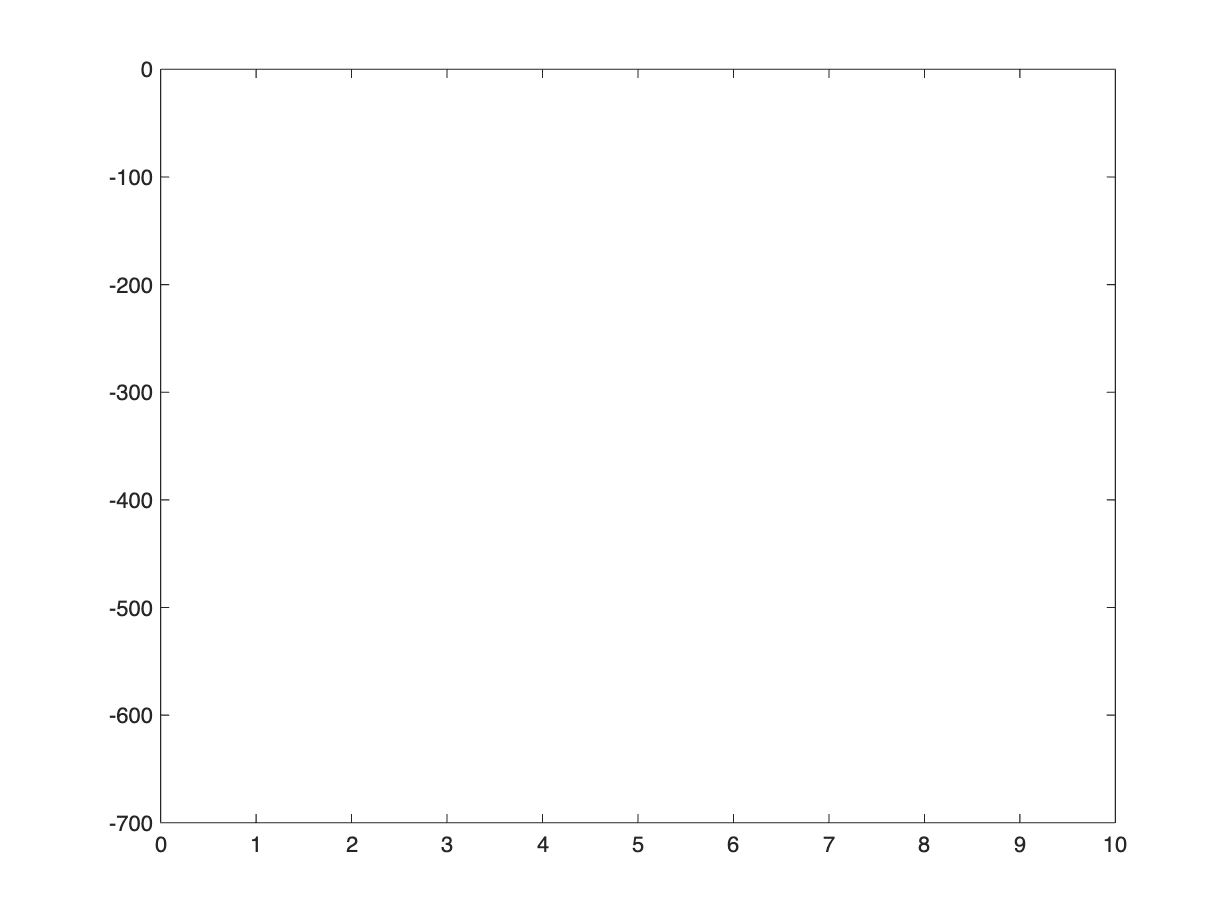

figure
plot(0:0.1:10,voltage_command(0:0.1:10,double(sol_ics.V0)),'Linewidth',2)
ylim([-700 0])

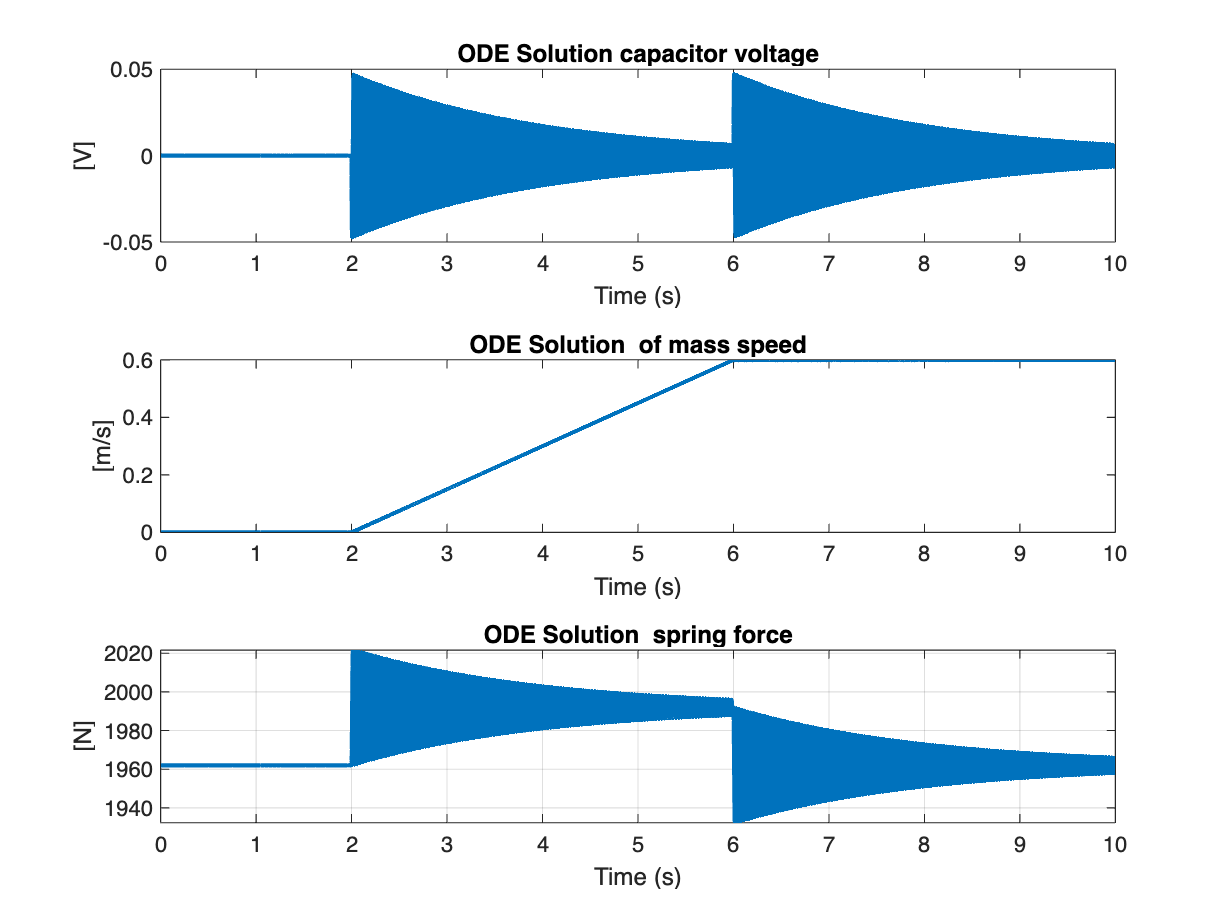



% call Runge Kutta integrator
[tSol, ySol] = ode45(@(t,x)ode_rhs(t,x,voltage_command(t,double(sol_ics.V0))), tspan, ics); % Solve the ODE using ode45

% Plot the results
figure;
tiledlayout(3,1)
nexttile
plot(tSol, ySol(:,1),'LineWidth',2);
xlabel('Time (s)');
ylabel('[V]');
title('ODE Solution capacitor voltage');
nexttile
plot(tSol, ySol(:,2),'LineWidth',2);
xlabel('Time (s)');
ylabel('[m/s]');
title('ODE Solution  of mass speed');
nexttile
plot(tSol, ySol(:,3),'LineWidth',2);
xlabel('Time (s)');
ylabel('[N]');
title('ODE Solution  spring force');



grid on;